# **Lab3 12210309 李志颖**

## **Problem 1**

clc;clear;close all;
colormap(gray);
f = fopen("raster");

### Right Situation

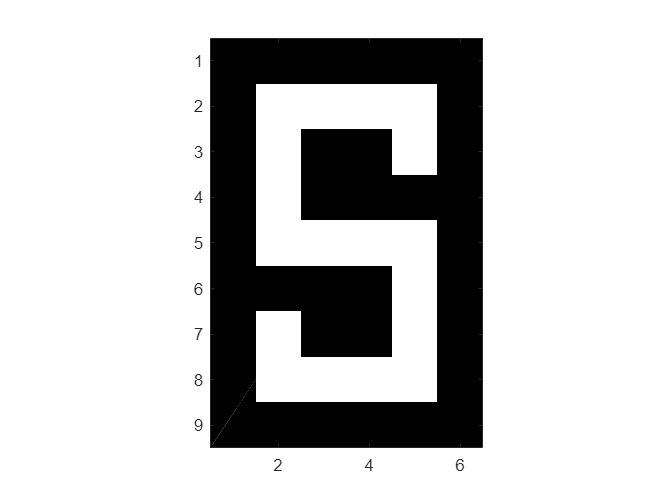

     0     0     0     0     0     0     0     0     0
     0     1     1     1     1     0     1     1     0
     0     1     0     0     1     0     0     1     0
     0     1     0     0     1     0     0     1     0
     0     1     1     0     1     1     1     1     0
     0     0     0     0     0     0     0     0     0

    54



problem1(f,6,9);

正确的图像如图所示

f = fopen("raster");

### Wrong Situation

     0     0     0
     0     1     1
     0     0     0
     0     0     0
     0     0     1
     0     0     0
     0     0     0
     1     1     1
     1     1     1
     1     1     1
     1     1     1
     0     0     0
     0     0     0
     1     0     0
     0     0     0
     0     0     0
     1     1     0
     0     0     0

    54



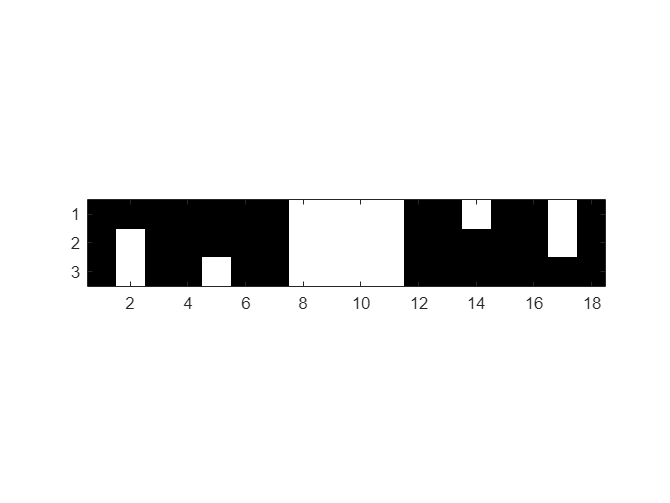

problem1(f,18,3)

不正确的图像如图所示

## Problem2

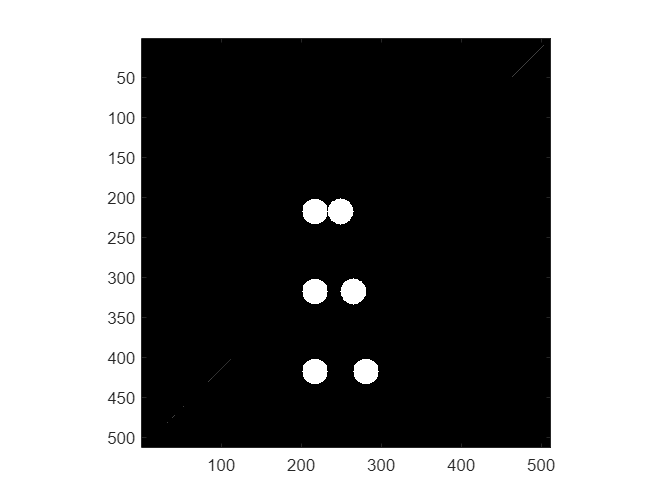

% 1
pix=zeros(512,512);

% 2
circle=ones(33,33); 
for i=1:33
    for j=1:33
        if(sqrt((i-17)^2+(j-17)^2))> 16 
            circle(i,j)=0; 
        end
    end
end
for i=1:33
 for j=1:33
     pix(i+200,j+200)=circle(i,j); 
     pix(i+232,j+200)=circle(i,j); 
     pix(i+200,j+300)=circle(i,j); 
     pix(i+248,j+300)=circle(i,j); 
     pix(i+200,j+400)=circle(i,j); 
     pix(i+264,j+400)=circle(i,j); 
 end
end
h=imagesc(pix'); 
axis ([0 512 0 512]); axis image;

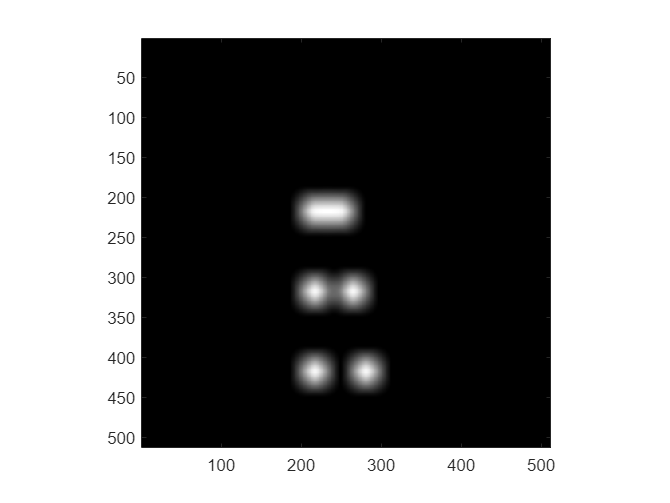

% 3 
filter=ones(33,33); 
pix2=filter2(filter,pix,'same');
h=imagesc(pix2'); 
axis ([0 512 0 512]); axis image;

*Answer*：在过滤后的图像中，顶部的圆无法区分，中间层的圆可以分开，但他们的边缘仍然模糊，最底层的两个圆被明显分开且无模糊边缘。

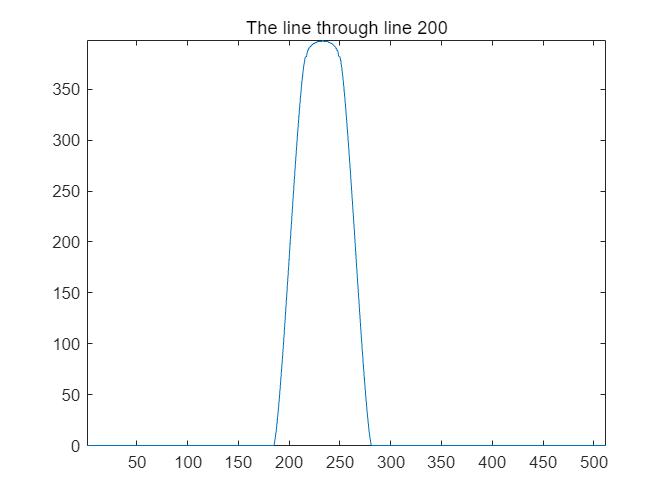

% 4
figure;
cutLine1 = pix2(:, 200);
figure;
plot(cutLine1); title('The line through line 200');
axis ([0 512 0 512]); axis image;

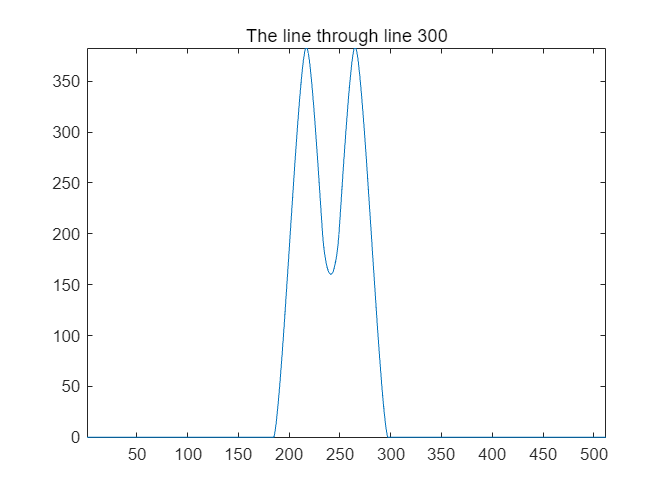

cutLine2 = pix2(:, 300);
figure;
plot(cutLine2); title('The line through line 300');
axis ([0 512 0 512]); axis image;

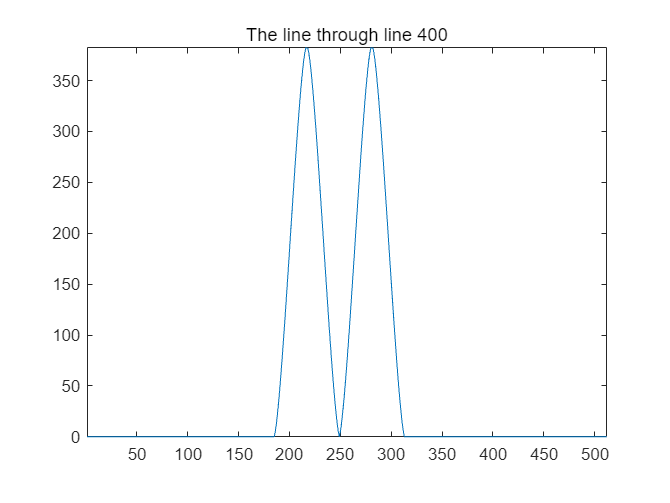

cutLine3 = pix2(:, 400);
figure
plot(cutLine3); title('The line through line 400');
axis ([0 512 0 512]); axis image;

*Answer：*通过三张图可以很明显的看出圆的重叠情况。第一张图表示了上层两个圆，两个圆的像素峰值完全融合在一起，因此不可分。第二张图表示了中层的两个圆，他们中间的像素值较低但不为零，因此他们中间部分模糊不可分。第三张图则表示了底层的两个圆，他们中间的像素值为零，因此他们两完全可分。

## Problem 3

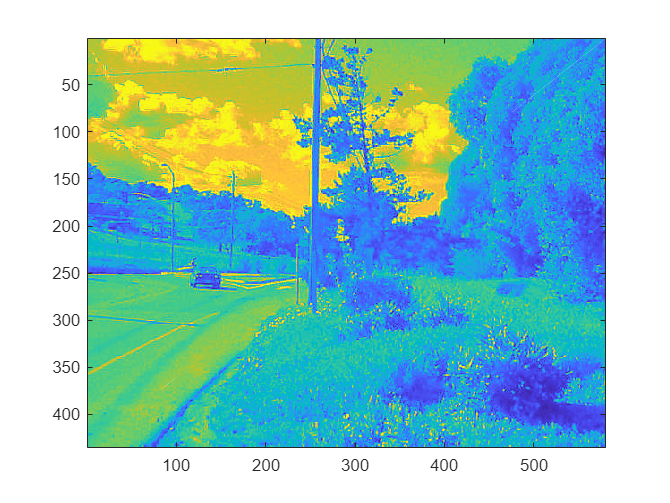

% 1
clear; clc; close all;
f=fopen('campusdrive'); 
a=fread(f,[580 inf],'uint8'); 
a = a';
imagesc(a);

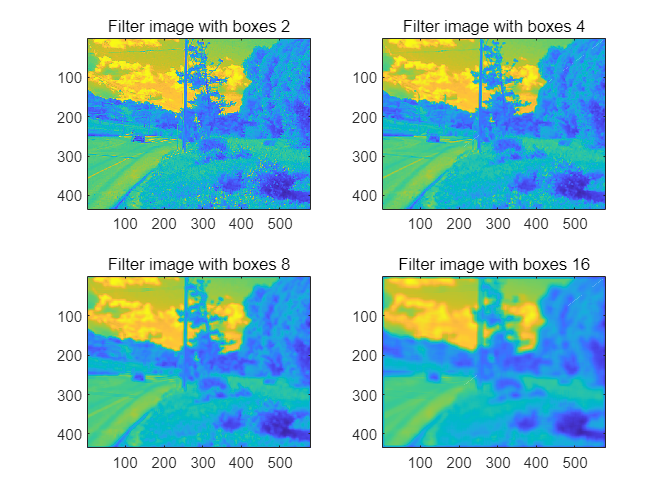

% 2
filter_1=ones(2,2); 
filter_2=ones(4,4);
filter_3=ones(8,8);
filter_4=ones(16,16);

a1=filter2(filter_1,a,'same');
a2=filter2(filter_2,a,'same');
a3=filter2(filter_3,a,'same');
a4=filter2(filter_4,a,'same');

figure;
subplot(2,2,1); imagesc(a1); 
title('Filter image with boxes 2')
subplot(2,2,2); imagesc(a2); 
title('Filter image with boxes 4')
subplot(2,2,3); imagesc(a3); 
title('Filter image with boxes 8')
subplot(2,2,4); imagesc(a4); 
title('Filter image with boxes 16')

*Answer:  *Boxes 2:  与原始图像基本相同，但可以观察到滤波后的图像开始变得平滑。

               Boxes 4：电线杆、白云和草的特征逐渐变得模糊。

               Boxes 8： 汽车，白云，草的一些特征都失去了。

               Boxes 16： 道路，白云，车，电线杆和树的特征基本都失去了。

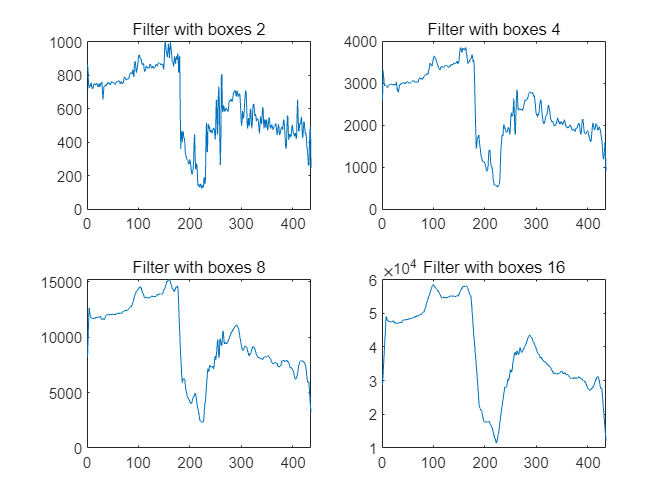

% 3 
y = 200;
cutLine1 = a1(:, y);
cutLine2 = a2(:, y);
cutLine3 = a3(:, y);
cutLine4 = a4(:, y);
figure;
subplot(2,2,1), plot(cutLine1); title('Filter with boxes 2')
subplot(2,2,2), plot(cutLine2); title('Filter with boxes 4')
subplot(2,2,3), plot(cutLine3); title('Filter with boxes 8')
subplot(2,2,4), plot(cutLine4); title('Filter with boxes 16')

## Problem 4

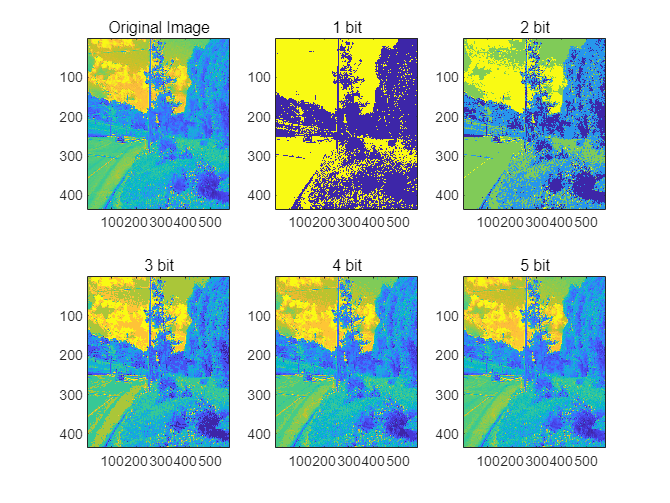

clear; clc; close all;
% 1
f=fopen('campusdrive'); 
a=fread(f,[580 inf],'uint8'); 
a = a';
% 2
a5bit = bitand(a, 128+64+32+16+8);
a4bit = bitand(a, 128+64+32+16); 
a3bit = bitand(a, 128+64+32); 
a2bit = bitand(a, 128 + 64); 
a1bit = bitand(a, 128);

figure;
subplot(2,3,1), imagesc(a); title('Original Image');
subplot(2,3,2), imagesc(a1bit); title('1 bit');
subplot(2,3,3), imagesc(a2bit); title('2 bit');
subplot(2,3,4), imagesc(a3bit); title('3 bit');
subplot(2,3,5), imagesc(a4bit); title('4 bit');
subplot(2,3,6), imagesc(a5bit); title('5 bit');

*Answer：*通过观察发现至少需要 3bit 才可以保证图像质量

## Problem 5

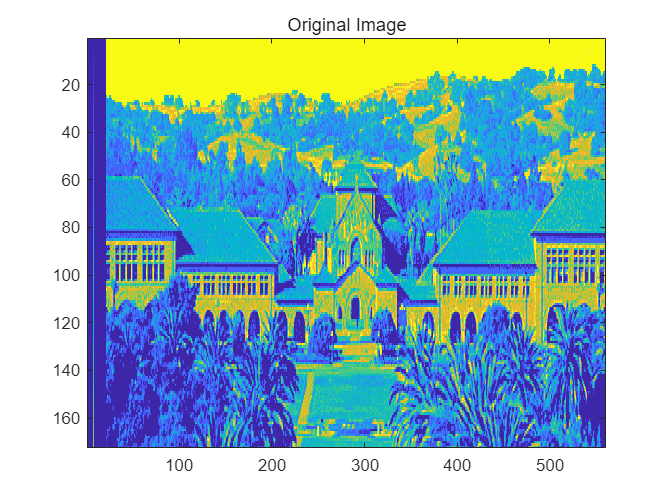

clear; close all; close all;
% 1
f = fopen('lab3prob5data','rb');
%2
a = fread(f,[560 inf],'uint8');
a = a';
imagesc(a); 
title('Original Image');

% 3  图`片的字`节`数`为 172*560*8`； `

`每行是 `172*8`；`

header area`：`172*20

% 4 
head_information = a(:, 8);

complete_data = 1:173;

missing_num = setdiff(complete_data, head_information);

disp(['图像中丢失的行是：', num2str(missing_num)]);

图像中丢失的行是：114


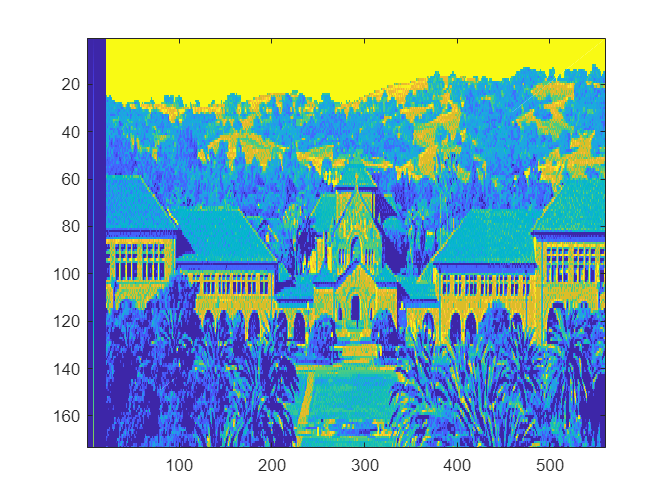

% 5 
row_temp = (a(113,:));
data_temp = [a(1:113,:);row_temp;a(114:end,:)];
imagesc(data_temp);

function problem1(f,row,width)
    [pix,count] = fscanf(f,'%d',[row, width]);
    disp(pix)
    disp(count)
    pix = pix';
    imagesc(pix);
    axis('equal'); axis('image');
end